# High-pass filtering

High-pass (HP) filtering is almost universally done in fMRI studies. fMRI data has a lot of noise at low temporal frequencies (slow drift). This is also a main source of autocorrelation in fMRI time series data. HP filtering models ("captures") and removes low-frequency signals. This can be done in the **time domain **and in the **frequency domain**. 

Filtering can also be done at the same time as fitting a linear model, by adding nuisance covariates to the design matrix, or it can be done before analysis by *pre-filtering*. Many software packages pre-filter because it's convenient, particularly for connectivity analyses where there is no experimental design matrix. Here, we'll look at a simple example of filtering by adding covariates to the design matrix.

Filtering is a linear operation, so it is possible to construct a matrix *S* that, when multiplied by the data (e.g., S*y), returns a filtered time series. Filtering can be used to condition time series data in multiple ways:

- High-pass filters remove low-frequency (slow) noise and pass high-freqency signals. 

- Low-pass filters remove high-frequency noise and thus smooth the data.  

- Band-pass filters allow only certain frequencies and filter everything else out

- Notch filters remove certain frequencies

There are also different ways of constructing filters: 

- Discrete cosine transform (DCT) filters use a bank of cosine waves (we will look at this here)

- Chebyshev and Butterworth filters are advanced filters designed to optimize certain properties (e.g., prevent "ringing")

Here, we'll go over some of the basics of how high-pass filtering works.

#### Refresher: Sine waves

The sine wave is an oscillation, which can be described mathematically as:


$$y=Asin(2\pi f t + \theta)$$


...where $f$is the frequency or the speed of the oscillation described in the number of cycles per unit time (e.g., second), $t$is the the time, and $\theta$ is the phase in radians.  $y$ is the signal value, and it can be a vector. If time is in units of seconds, frequency in units of 1/time, or hertz (𝐻𝑧). Amplitude 𝐴 determines the height of the waves:  𝐴 is half the distance of the peak to the trough. 

Here we will plot a simple sine wave. Try playing with the different parameters (i.e., amplitude, frequency, & theta) to gain an intuition of how they each impact the shape of the wave.

More detailed explanations can be found on Michael X. Cohen's excellent [Youtube channel](https://www.youtube.com/watch?v=fYtVHhk3xJ0&list=PLn0OLiymPak2jxGCbWrcgmXUtt9Lbjj_A&index=1) and in his book, [Analying Neural Data Analysis: Theory and Practice](https://www.amazon.com/Analyzing-Neural-Time-Data-Practice/dp/0262019876). Here is a picture from one of Mike's videos that shows the relationship between time domain signals (top row) and frequency domain signals (bottom row) for some simple sine waves:

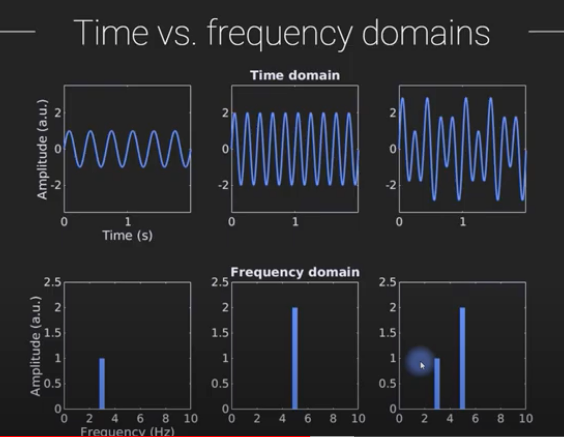

First, we'll create an anonymous function in Matlab that lets us plug in any values for *A*, *f*, and $\theta$. We'll fix the value of *t *to be a vector from 0 to 360 seconds, about the length of a typical fMRI run. This will be sampled at a high rate (100 Hz!), though fMRI data will be collected much slower, around 2 sec per BOLD image or 1/2 Hz for old studies or 0.5 sec per image (2 Hz) for newer multiband imaging studies. (The actual sampling rate is the Repetition Time, TR).

t = 0:.01:360;   % time samples for the underlying signal

sinwave = @(A, F, theta) A .* sin(2 * pi * F * t + theta);

**Questions to answer:**

- Create a signal with amplitude 2 and a 20-sec period and plot it.  

            Hints: Play around with the input parameters. Your signal will look strange if it's oscillating too fast to see clearly.  Period is 1/F. e.g., to create a wave with amplitude 3 and 10 sec period, try this:

         2. What happens when you shift the phase over by pi/2 radians? Plot it.  What kind of wave looks just like this? (e.g., not a sine wave, but a...)

         3.  Create a signal that sums three sine waves, with 1.5 sec, 20 sec, and 50 sec periods, and amplitudes of 1, 2, and 3, respectively. 

        Hint: It should look like this:

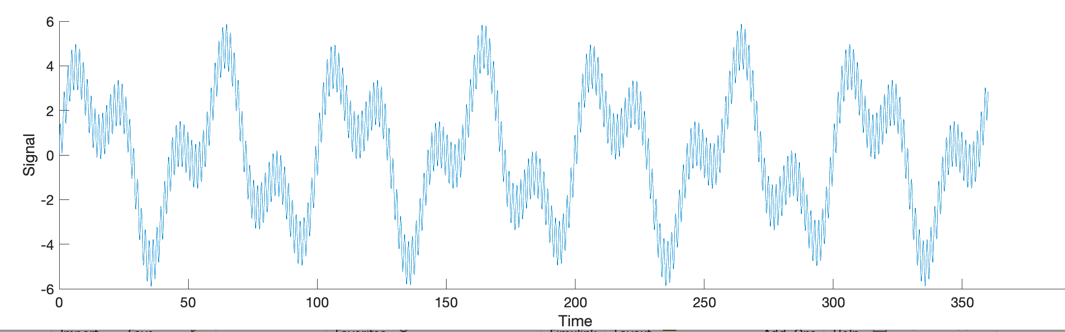

And you can sum sin waves like this:

#### Fourier Transform

Now we'll take the Fourier Transform, decomposing the signal into sin waves. The real part of this is the signal magnitude, or  the **power spectrum** -- power across a spectrum of frequencies**. ** The Nyquist frequency is 1/2 the sampling rate, so we'll show that too:

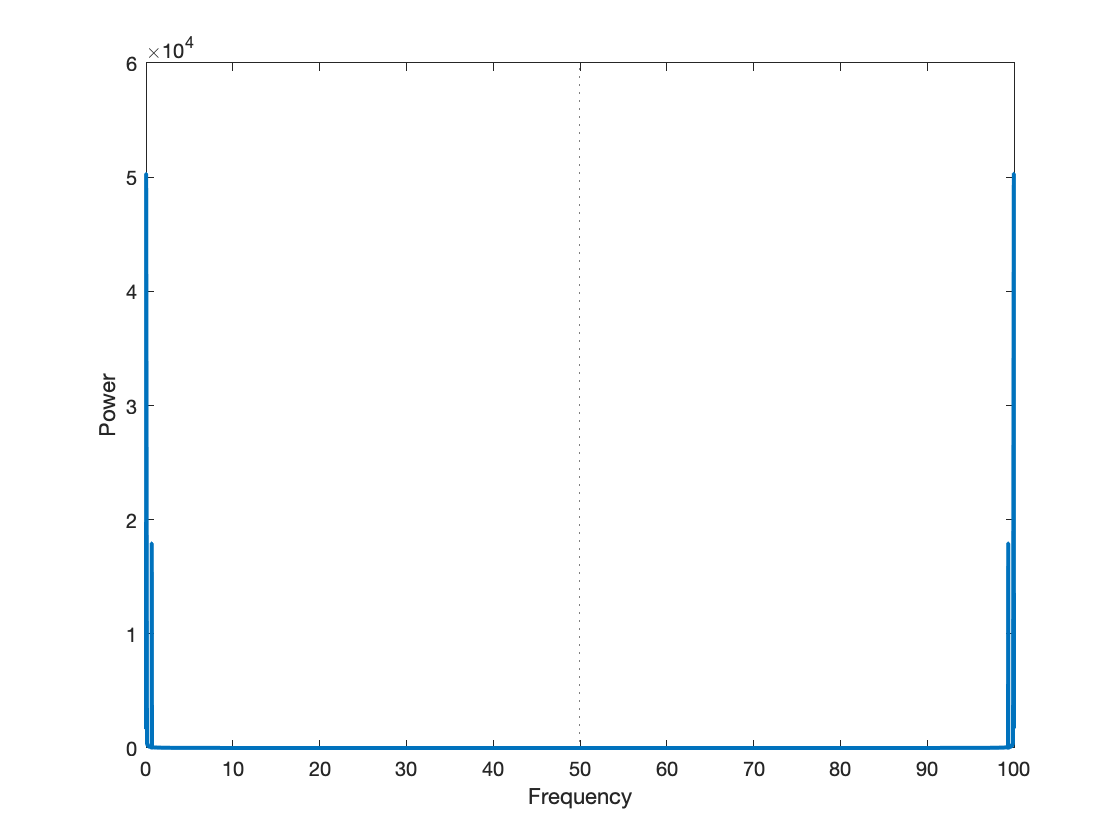

yf = fft(y);        % Fourier transform
mag = abs(yf);      % Signal magnitude (the real part)

F = 100;           % Our original sampling frequency in Hz
f = F .* (0:(length(y)-1))/length(y); % define frequencies for each element of yf
 
nyquist = F ./ 2;  % Any signal faster than Nyquist freq will be aliased

figure; plot(f, mag, 'LineWidth', 2); hold on; 
xlabel('Frequency'); ylabel('Power')

h = plot_vertical_line(nyquist);
set(h, 'LineStyle', ':')

Notice that the signal is reflected around the Nyquist limit.  Anything moving faster than that is "invisible", as it's aliased back into the lower frequencies. Let's zoom in on the relevant part by setting the X-axis limits in the display.  This is a "graphics handle" in Matlab. You can adjust figures in many ways, either through the buttons on the figure (or by clicking/scolling in the figure), or with code.

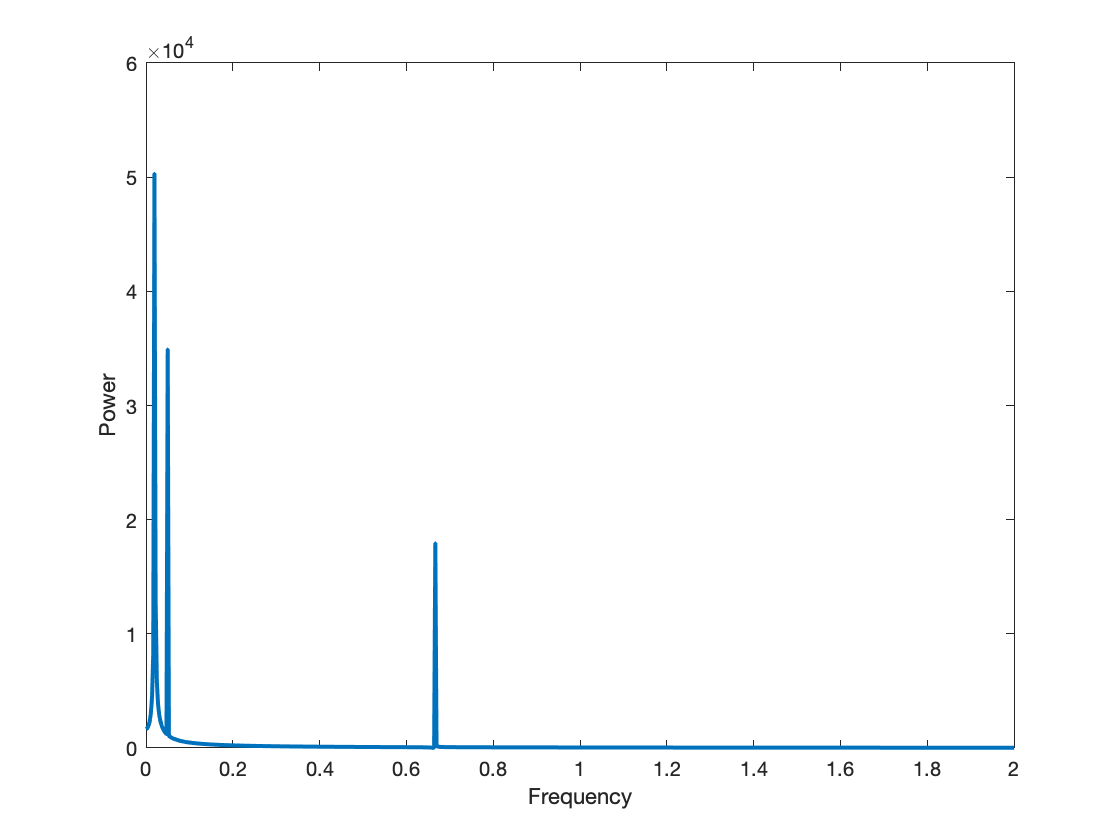

figure; plot(f, mag, 'LineWidth', 2); hold on; 
xlabel('Frequency'); ylabel('Power')
set(gca, 'XLim', [0 2])  % Zoom in on frequencies from 0 (constant, fundamental frequency) to 2 Hz

It should look like this:

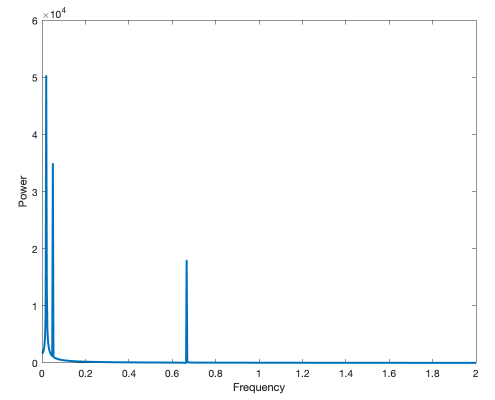

#### Downsampling

In fMRI, we sample signals that have a mix of frequencies, including high-frequency oscillations, at a slower sampling rate. A simple way to downsample our signal is to take every *n*th sample. If our original signal is 100 Hz and we want to simulate sampling at 0.5 Hz, we'd take every 100/0.5 = 200th sample.

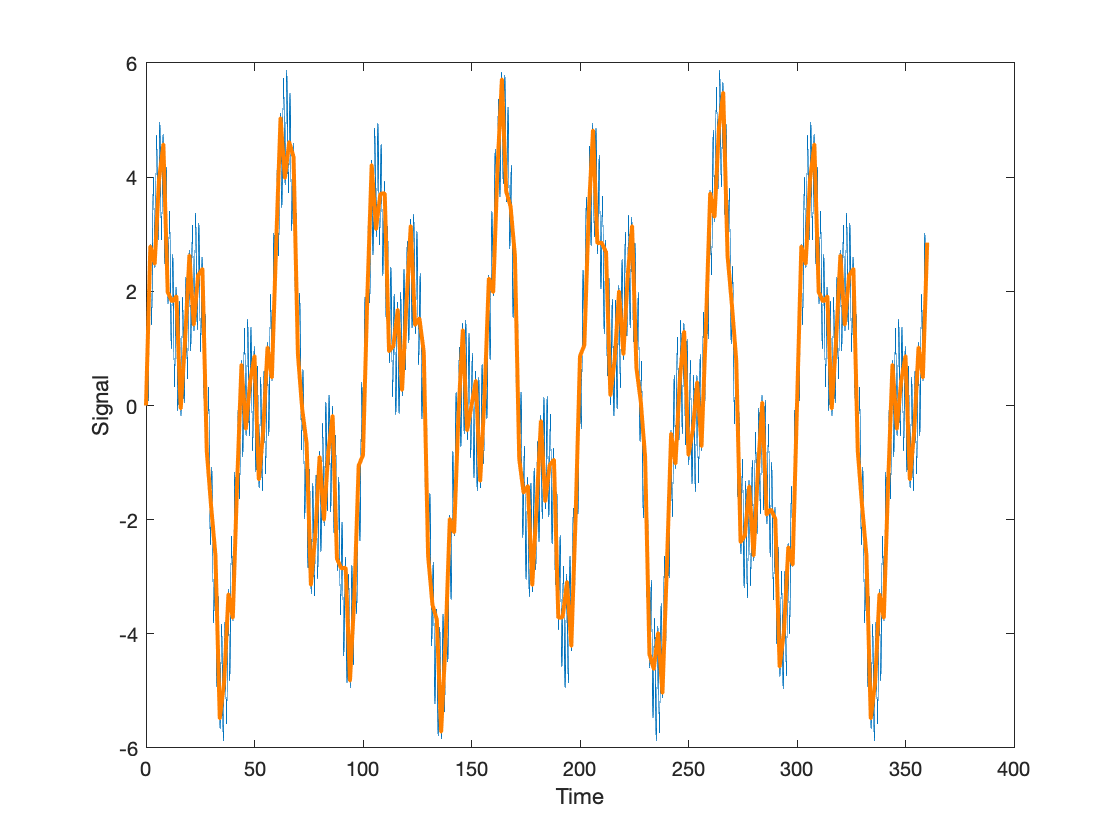

t_obs = t(1:200:end);
y_obs = y(1:200:end); 

figure; plot(t, y);  % plot underlying signal in blue
xlabel('Time'); ylabel('Signal'); hold on; 
plot(t_obs, y_obs, 'LineWidth', 2, 'Color', [1 .5 0])  % plot sampled signal in orange with a heavier line

**Questions to answer:**

- Show the plot. What information in the signal have we lost? What is retained?

         2. Do the fft on the downsampled signal, and re-create a plot of the power in the original signal, adding the new signal in orange to the plot. You can use the code below.  What frequencies have been lost? Which ones have appeared?  What is the Nyquist limit for the downsampled signal, and how does this help explain the plot? 

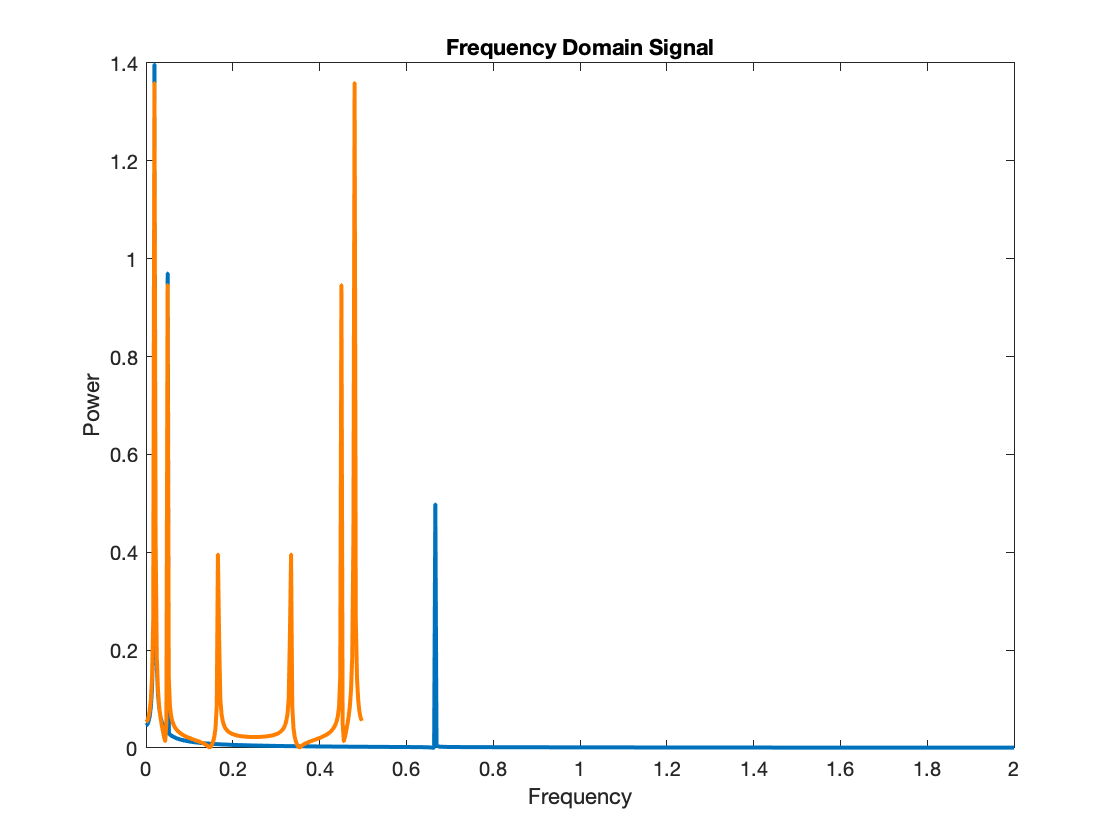

figure; plot(f, mag ./ length(y), 'LineWidth', 2); hold on; 
xlabel('Frequency'); ylabel('Power')
set(gca, 'XLim', [0 2]) 

mag_obs = abs(fft(y_obs)) ./ length(y_obs);      % Signal magnitude (the real part)
f_obs = F/200 .* (0:(length(y_obs)-1))/length(y_obs); % define frequencies for each element of yf

hold on; plot(f_obs, mag_obs, 'Color', [1 .5 0], 'LineWidth', 2);
title('Frequency Domain Signal')

### Filtering

Recall from our signal processing tutorial, that there are often other types of artifacts in fMRI signal that might take the form of slow or fast oscillations. It is common to apply a **high pass filter** to the data to remove low frequency artifacts. This does what it sounds like: It passes high frequencies, and removes low frequencies below a certain cutoff. 

A high-pass filter has to model  ("capture") and remove low-frequency signals. We can think of this in two ways: in the **time domain**, and in the **frequency domain**.  

In the **time domain**, we'll add regressors that capture slowly-varying signals and remove their fitted responses from the data, or "residualize" the data. These could be any slowly varying curve: polynomials, splines, or others. They could also be a set of sine or cosine waves. These regressors will be added to our model (design matrix, X) as nuisance covariates. Recall the linear model equation $y=X\beta+\epsilon$.  *X* contains regressors of interest.  I can add new columns of X to capture the nuisance covariates.

In the **frequency domain**, we can multiply the power spectrum by a filter, which is a series of values. Where the filter values are zero, those frequencies are filtered out. These two ways of thinking about filters are different ways of representing the same process, just as the time-domain and frequency domain signals are actually just different expressions of the same signal.

#### Create an fMRI design and add high-pass filter covariates 

Let's create a simple fMRI design and use it to simulate a signal. We'll add noise with some slow drift at specific frequencies so we can unpack what's going on:

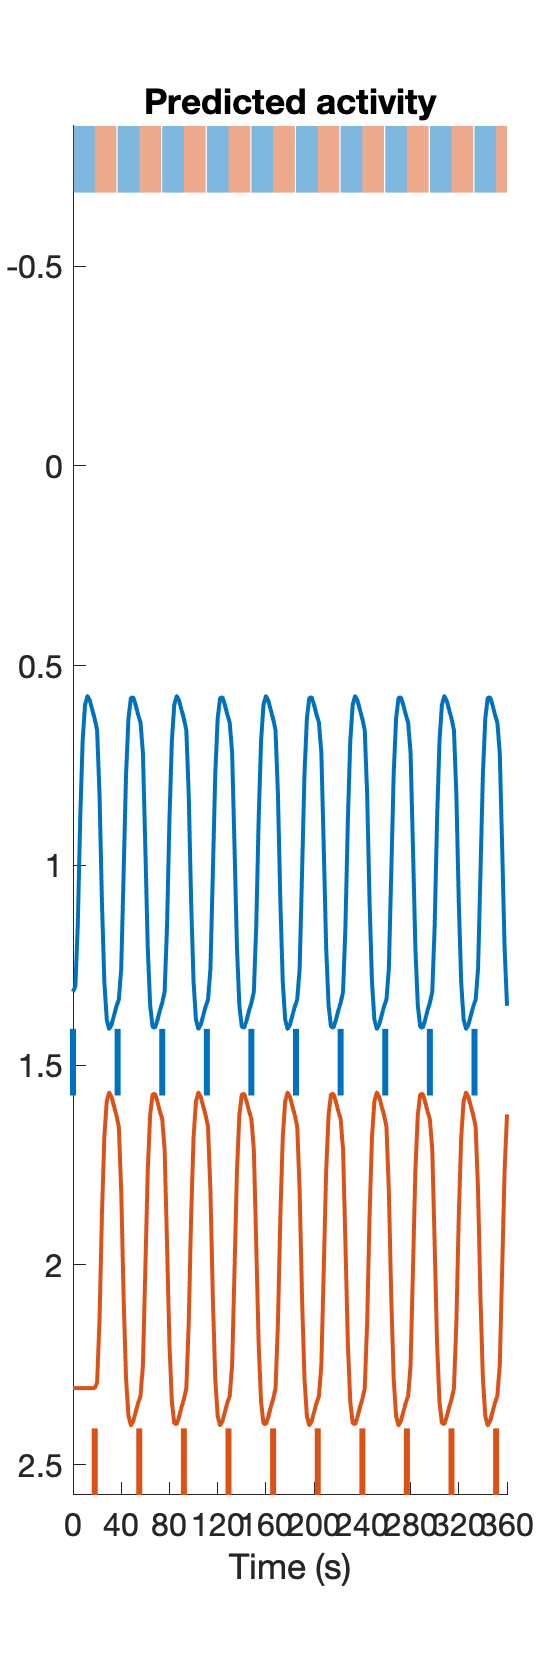

TR = 2;
create_figure('Simple fMRI study with 2-condition block design');
X = create_block_design(360, TR, 2, 18, Inf, 0);

% The second predictor is a mirror-image of the first, so let's save the first only as our predictor of interest
X = X(:, 1);

create_figure('2-condition block design', 3, 1); 
t = 0:2:(360-1);
plot(t, X); xlabel('Time (sec)')
title('True signal: Time domain')

% Now create a signal with some faster noise and slow drift:

%y1 = sinwave(1, 1, 0);  % F = 1 Hz = 1 sec. This is like a heart-beat signal. It will be aliased!
y2 = sinwave(2, 1/10, 0); % F = 1/30 Hz, 30 sec period
y3 = sinwave(5, 1/60, 0); % F = 1/30 Hz, 60 sec period
y4 = sinwave(8, 1/120, 0); % F = 1/120 Hz

y_drift = y2 + y3 + y4;
y_drift = y_drift(1:100 * TR:end - (100 * TR))'; % downsample and make a column vector

y = X + y_drift;

subplot(3, 1, 2)
plot(t, y, 'Color', 'k', 'LineWidth', 2);
title('Signal with slow drift')

% Now let's look at the FFT. We'll use periodogram( ) to simplify 
[mag, f] = periodogram(X, [], [], 1/TR);
max_freq = f(mag == max(mag));
fprintf('True signal: Max power at %3.2f Hz or %3.1f sec periodicity\n', max_freq, 1/max_freq);

True signal: Max power at 0.03 Hz or 36.6 sec periodicity


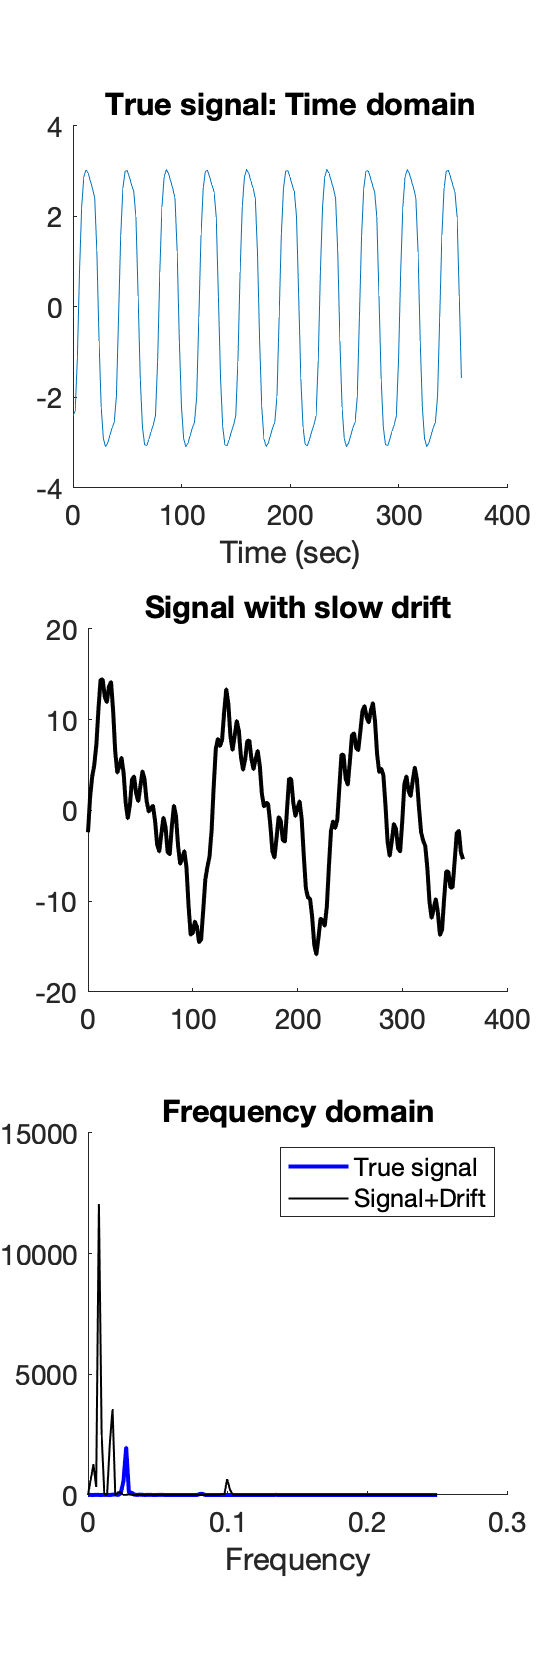


subplot(3, 1, 3)
plot(f, mag, 'LineWidth', 2, 'Color', 'b');
xlabel('Frequency')
title('Frequency domain')

% Add the power spectrum for the noise:
[mag, f] = periodogram(y_drift, [], [], 1/TR);
plot(f, mag, 'LineWidth', 1, 'Color', 'k');
legend({'True signal' 'Signal+Drift'});

Now we're ready to construct a filter matrix. discrete cosine transform (DCT), which is a basis set of cosine regressors of varying frequencies up to a filter cutoff of a specified number of seconds. Many software use 100s or 128s as a default cutoff, but we encourage caution that the filter cutoff isn’t too short for your specific experimental design. Longer trials will require longer filter cutoffs. See this [paper](https://www.sciencedirect.com/science/article/pii/S1053811900906098) for a more technical treatment of using the DCT as a high pass filter in fMRI data analysis. In addition, here is a more detailed discussion about [filtering](http://mindhive.mit.edu/node/116).   

We'll use a DCT built into [SPM software](https://www.fil.ion.ucl.ac.uk/spm/software/spm12/) for this, and specifically *spm_filter( ). *This takes a struct variable with specific fields as input, which tells it how to construct the matrix. HParam is the filter period in seconds. TR is the samping time, as above.

K_input = struct('RT', TR, 'HParam', 100, 'row', ones(1, length(y)));
K = spm_filter(K_input);
K = K.X0;

create_figure('Filter matrix', 1, 2); 
imagesc(K); 
set(gca, 'YDir', 'Reverse'); axis tight
title('Heatmap view')

subplot(1, 2, 2); 
plot_matrix_cols(K)

ans =   1×7 Line array:

    Line    Line    Line    Line    Line    Line    Line


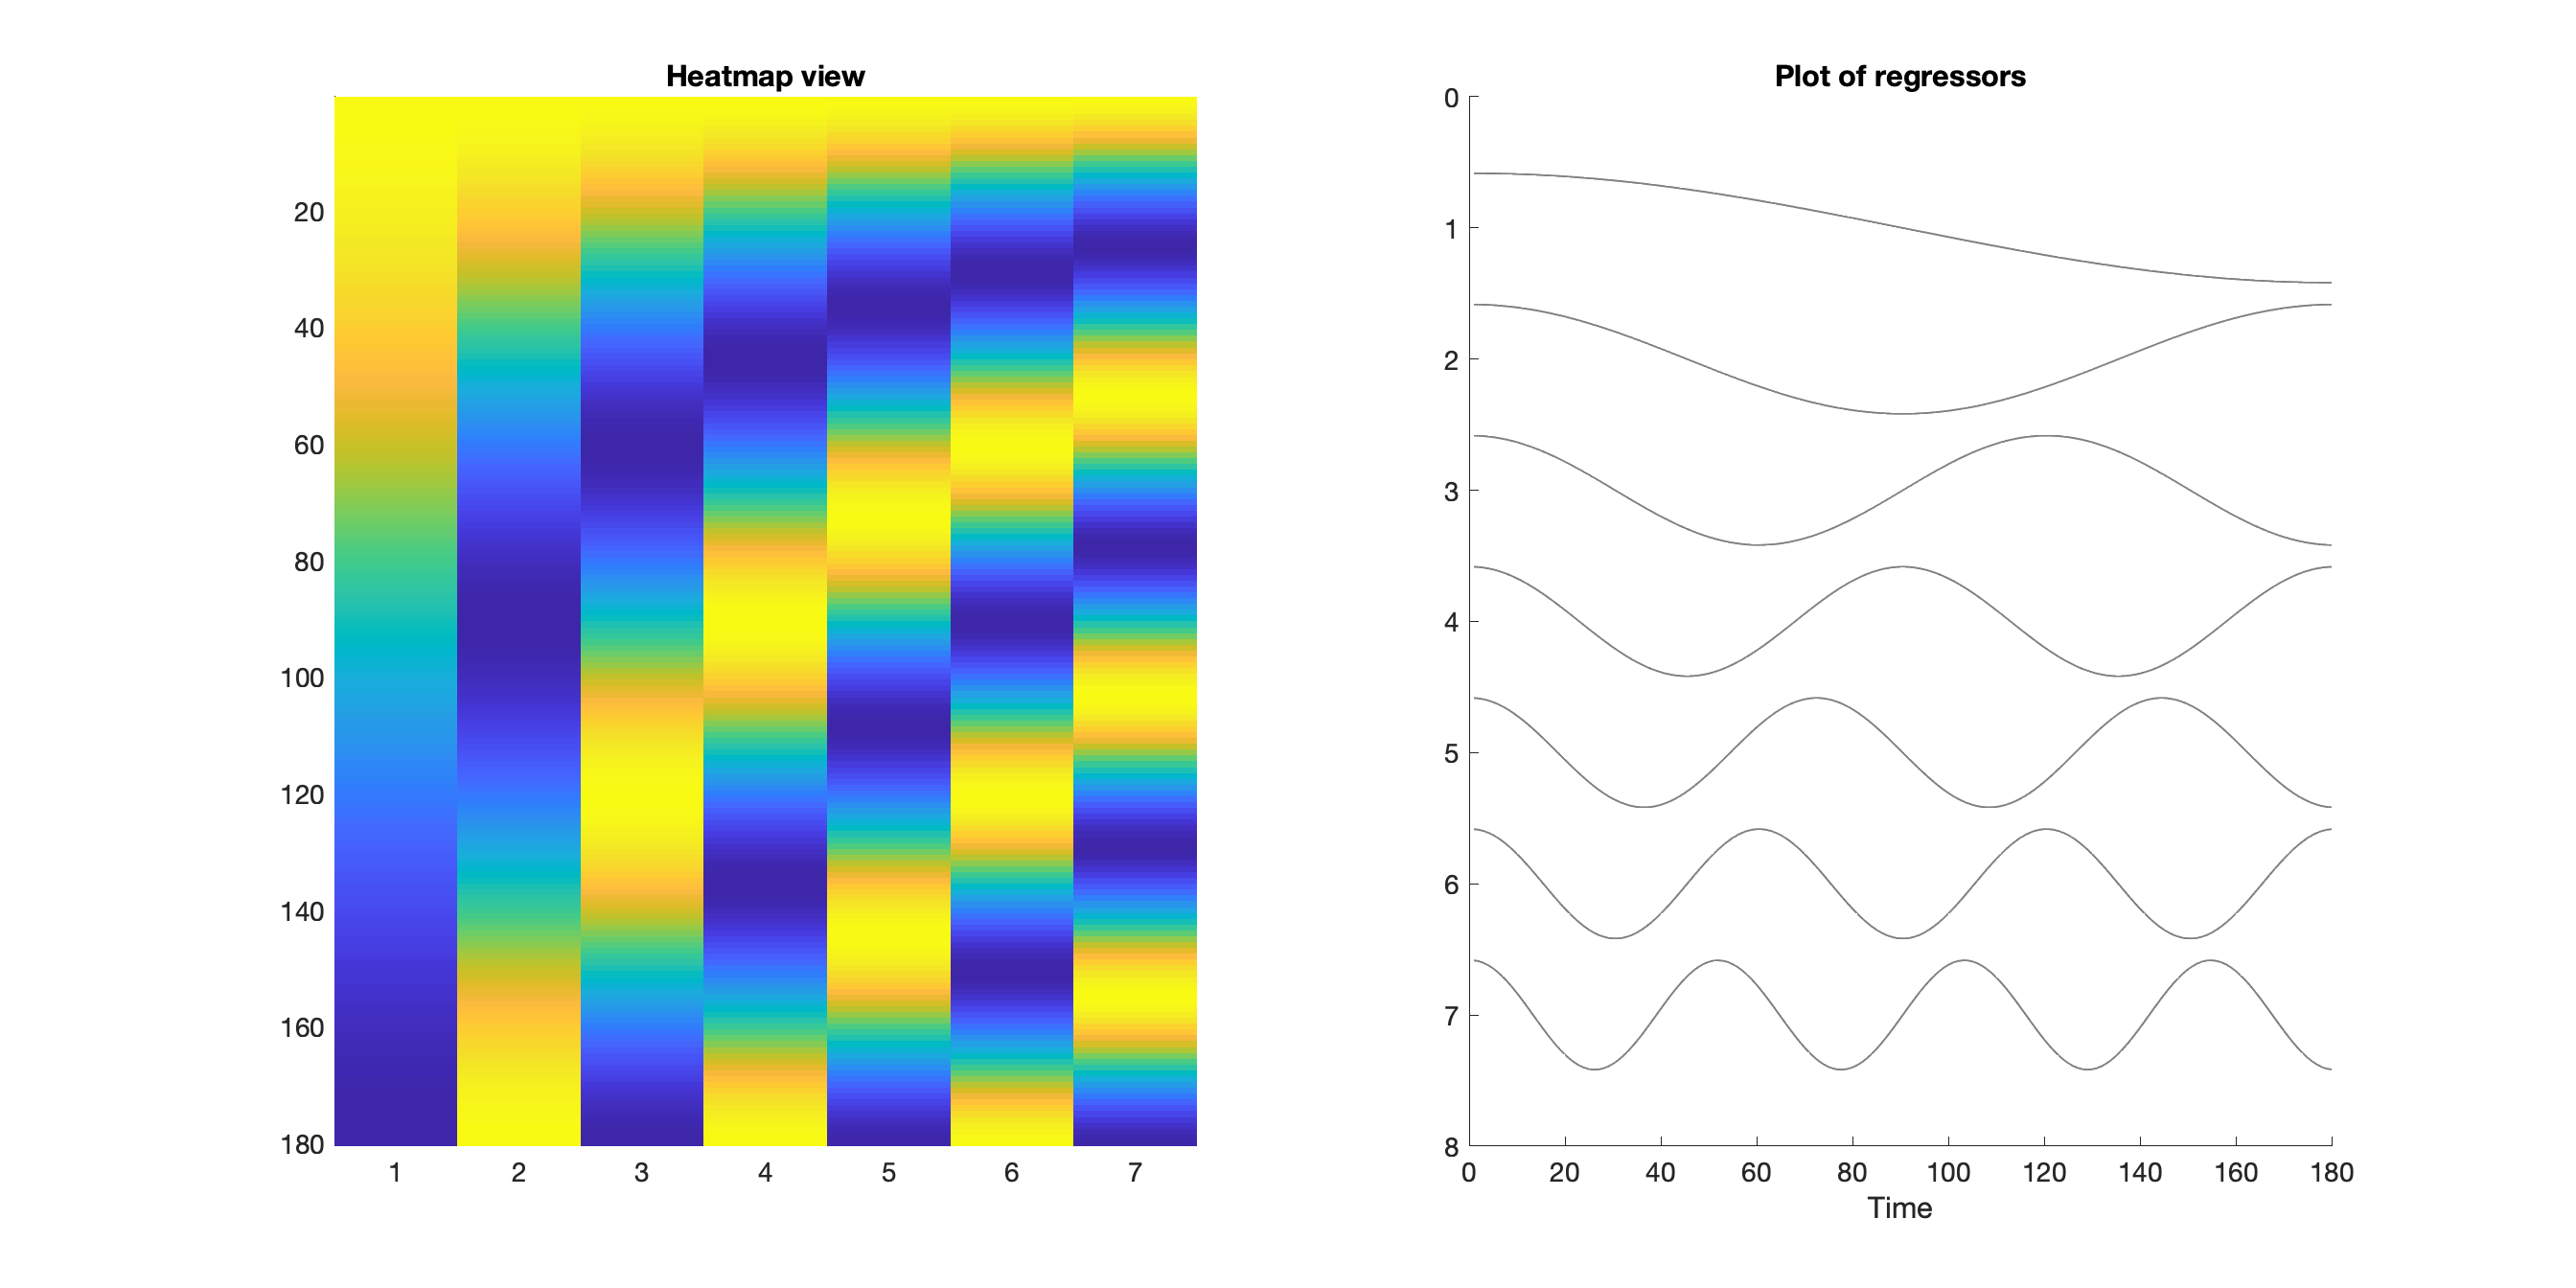

xlabel('Time')
title('Plot of regressors')

We can also look at the filter in frequency domain:

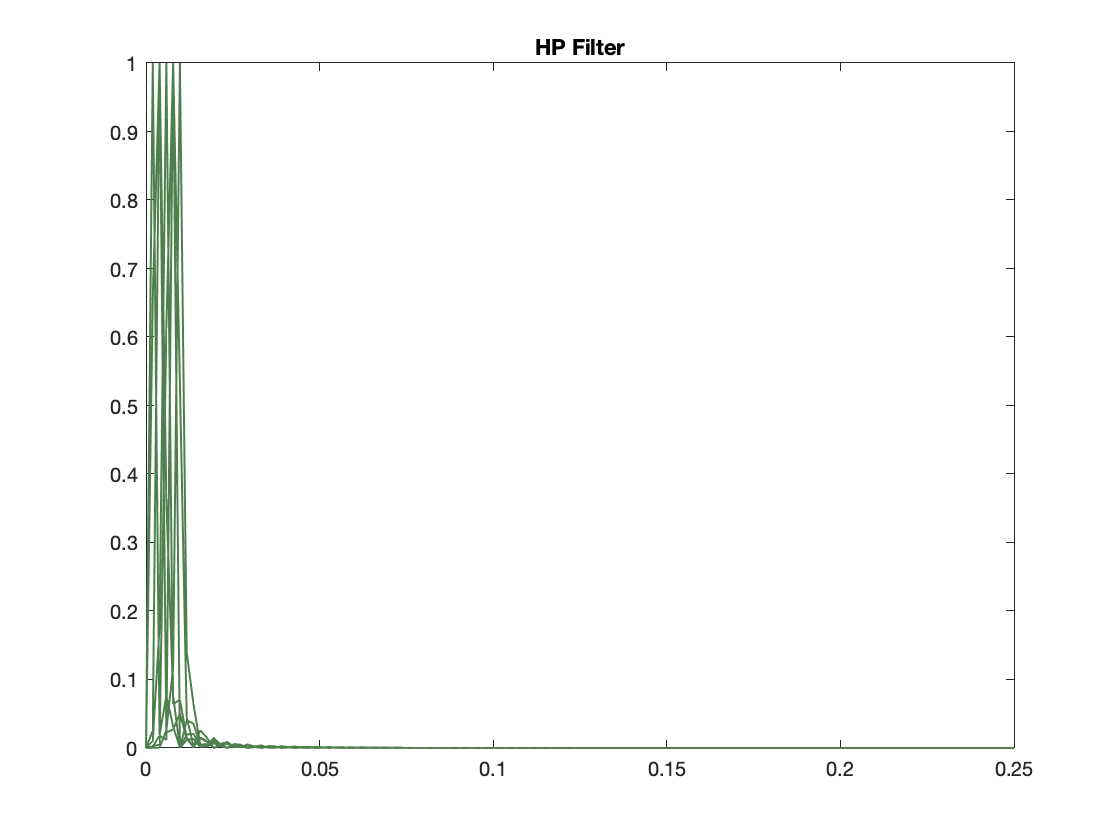

figure; 
[mag, f] = periodogram(K, [], [], 1/TR);
mag = mag ./ max(mag); % normalize r and K magnitudes to same scale so we can see both
plot(f, mag, 'LineWidth', 1, 'Color', [.3 .5 .3]);
title('HP Filter')

#### Questions to answer:

- Create code to plot the full design matrix. You can choose what type: imagesc( ) or plot_matrix_cols( ) are both good options. Add x-axis and y-axis labels and a title. Which column(s) represent the task and which represent nuisance covariates?

- Plot the pairwise correlations among the regressors, and the VIFs.  Is there a multicolinearity issue? Why/why not?

#### Fit the model and assess significance with and without filtering

Now, let's fit the model.  First we'll look at the model alone, without covariates. We'll use a CANlab function, *glm_table( )*, to make a simple table:

disp('Without filter covariates')

Without filter covariates


[b dev stat] = glmfit(X, y);    % The intercept is added automatically as the first predictor
glm_table(stat, {'Task'});

        Name            Beta          SE           t             p           Sig  
    _____________    ___________    _______    __________    __________    _______

    {'Intercept'}    -2.1605e-17    0.51111    -4.227e-17             1    {' '  }
    {'Task'     }         1.0116    0.20919        4.8359    2.8559e-06    {'***'}



Let's add the HP filter regressors as nuisance covariates:

disp('With filter covariates')

With filter covariates


[b dev stat] = glmfit([X K], y);

covnames = cell(1, size(K, 2));
[covnames{:}] = deal('Cov');

glm_table(stat, [{'Task'} covnames]);

        Name            Beta          SE            t             p           Sig  
    _____________    ___________    _______    ___________    __________    _______

    {'Intercept'}    -1.3501e-16    0.27426    -4.9227e-16             1    {' '  }
    {'Task'     }         1.0459    0.11269         9.2812    7.3973e-17    {'***'}
    {'Cov'      }         21.909     3.6798         5.9539     1.448e-08    {'***'}
    {'Cov'      }       -0.07057     3.6836      -0.019158       0.98474    {' '  }
    {'Cov'      }          27.11     3.6798         7.3673    7.0833e-12    {'***'}
    {'Cov'      }      -0.072901     3.6839      -0.019789       0.98423    {' '  }
    {'Cov'      }         59.022     3.6799         16.039    6.3782e-36    {'***'}
    {'Cov'      }        -4.0492     3.

Now we can plot the "data", the partial fit from the covariates, and the partial fit from the task.  We'll add the intercept to each partial fit to keep it in the same range as the data.

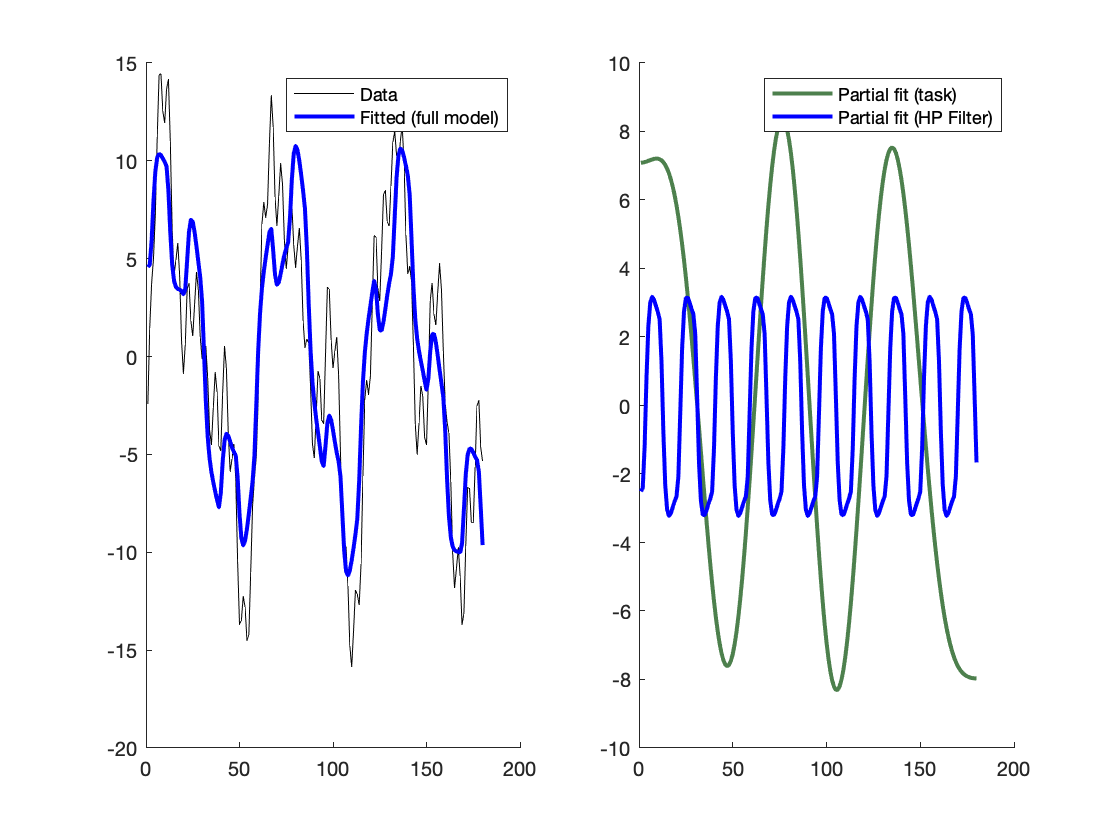

% create design matrices with intercepts to reconstruct fits
% glmfit adds the intercept first, so we will too.
Xfull = [ones(size(X)) X K]; 
Xi = [ones(size(X)) X];  
Ki = [ones(size(X)) K];  

fit = Xfull * stat.beta;
fit_task = Xi * stat.beta(1:2);
fit_drift = Ki * stat.beta([1 3:end]);

figure; 
subplot(1, 2, 1); hold on;
plot(y, 'k')
plot(fit, 'b', 'LineWidth', 2)
legend({'Data' 'Fitted (full model)'})

subplot(1, 2, 2); hold on;
plot(fit_drift, 'Color', [.3 .5 .3], 'LineWidth', 2)
plot(fit_task, 'b', 'LineWidth', 2)
legend({'Partial fit (task)' 'Partial fit (HP Filter)'})

Now we'll make a slightly different plot, a partial residual plot. This shows the relationship between the partial fit from a subset of regressors and the residuals after adjusting for other regressors in the model. The partial residuals show the data, leaving in an effect of interest but removing other effects we can account for with the model. For example, the partial residual for task shows the data after removing the fitted drift (black line) against the fit for task (blue line).

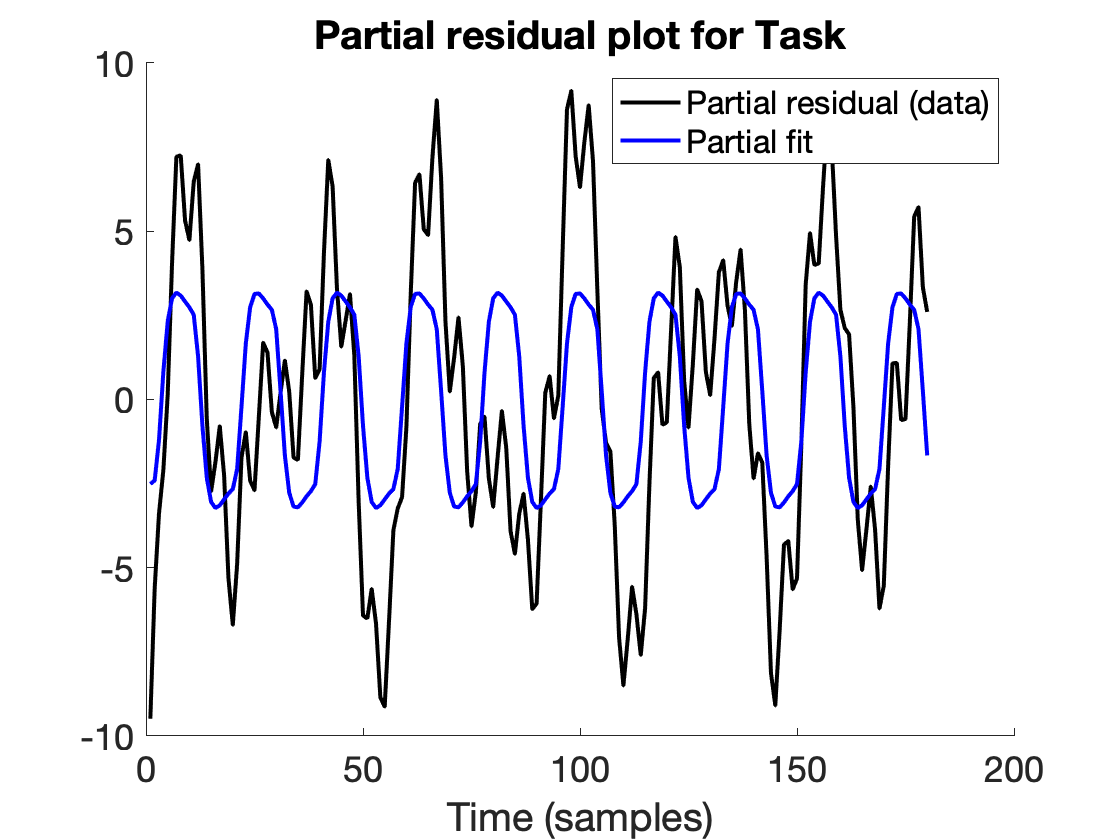

timeseries_prplot(y,[X K], 1);
title('Partial residual plot for Task');
xlabel('Time (samples)');

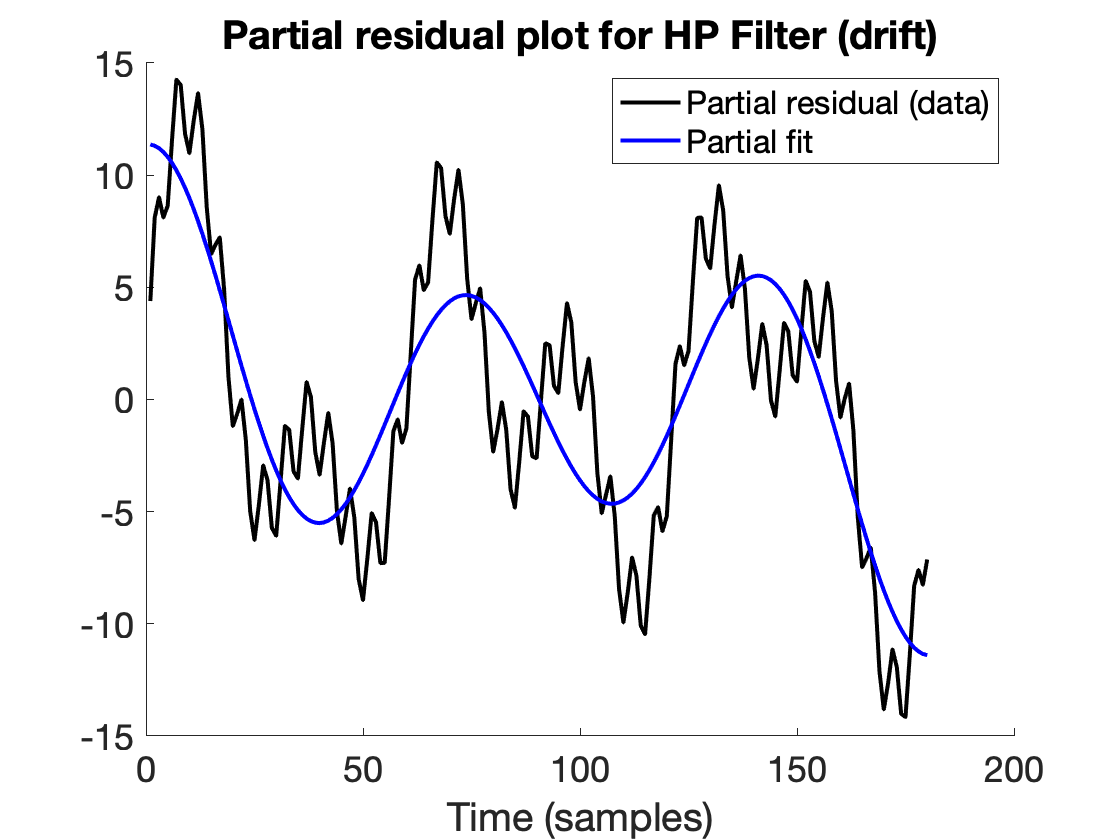


timeseries_prplot(y,[X K], [2:size(K, 2)-1]);
title('Partial residual plot for HP Filter (drift)');
xlabel('Time (samples)');

#### Questions to answer

- Did the filtering help?  Why do you think so?

- Did the filter remove all the drift elements in the signal?  What evidence do you have for your answer?

#### Looking at filtering in the frequency domain

So how good a job did our filter do? It seems to have removed much of the slow drift.


create_figure('Frequency domain', 1, 2)

ans =   Figure (Frequency domain) with properties:

      Number: 17
        Name: 'Frequency domain'
       Color: [1 1 1]
    Position: [561 529 560 420]
       Units: 'pixels'

  Show all properties


set(gca, 'XLim', [0 0.12])

[mag, f] = periodogram(y, [], [], 1/TR);
plot(f, mag, 'LineWidth', 1, 'Color', 'k');

[mag, f] = periodogram(fit_task, [], [], 1/TR);
plot(f, mag, 'LineWidth', 1, 'Color', 'b');

[mag, f] = periodogram(fit_drift, [], [], 1/TR);
plot(f, mag, 'LineWidth', 1, 'Color', [.3 .5 .3]);

legend({'Data' 'Fit from task' 'Fit from HPfilter'})


Now let's plot the power spectrum of the residuals (errors), and also add the HP filter, so we can see which part of the nuisance (drift) signal we have not captured, if any.

% Get the overall residuals and plot them
r = y - fit;

subplot(1, 2, 2)
[mag, f] = periodogram(r, [], [], 1/TR);
mag = mag ./ max(mag); % normalize r and K magnitudes to same scale so we can see both
plot(f, mag, 'LineWidth', 1, 'Color', 'k');
title('Power spectrum of residuals (error)')

% Let's pull out the max frequency of the residuals so we know what it is precisely
max_freq = f(mag == max(mag));
fprintf('Residuals: Max power at %3.2f Hz or %3.1f sec periodicity\n', max_freq, 1/max_freq);

Residuals: Max power at 0.02 Hz or 56.9 sec periodicity


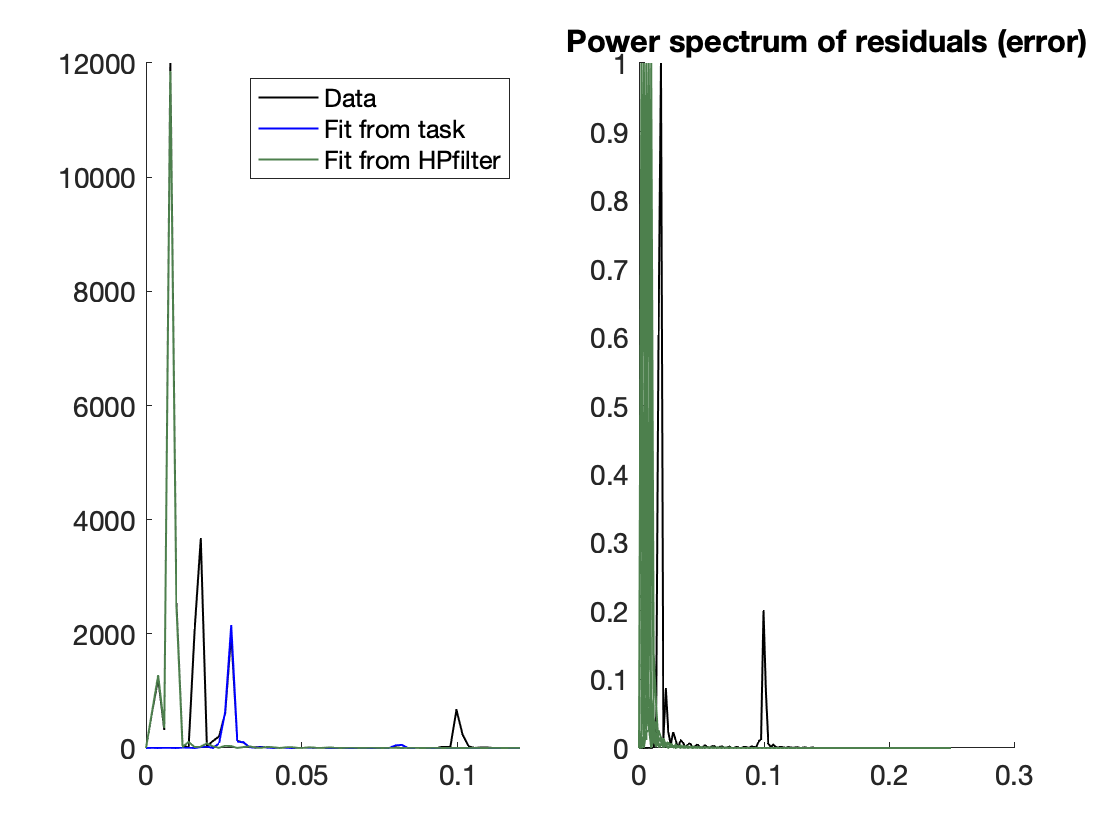


[mag, f] = periodogram(K, [], [], 1/TR);
mag = mag ./ max(mag); % normalize r and K magnitudes to same scale so we can see both
plot(f, mag, 'LineWidth', 1, 'Color', [.3 .5 .3]);

**Questions to answer**

- Compare the max frequency in the residuals to the upper bound frequency in our HP filter (Hz = 1 / period in sec). Based on these numbers, why does it make sense that the drift is not complely removed?

- What would happen if we tried to reduce the HP filter period (remove more frequencies) so that we remove *all* the drift frequencies we entered? Would the task effect become more significant (stronger)? Why/why not?

- How would you adjust the HP filter above to remove more of the nuisance effects (drift)? i.e., What new HP filter cutoff would you use?  

- Try it! construct a new K matrix, fit the model with the new covariates [X K] and plot the partial residual plot for the task. How does it look?

**Pre-filtering**

Filtering is a linear operation, so it is possible to construct a matrix *S* that, when multiplied by the data (e.g., S*y), returns a filtered time series. Typically in fMRI, we filter each voxel's time series separately -- that is often around 100,000 voxels!  If you are pre-filtering, e.g., for purposes of connectivity analyses, it's convenient to define *S* only once and then apply it to all the data.

The CANlab function *hpfilter( ) *uses SPM's high-pass filter (see above) to define a filter matrix S. It can also deal with multiple sessions (blocks) of data, where you'd like to model a different mean value for each block with a separate intercept (we'll deal with that later).

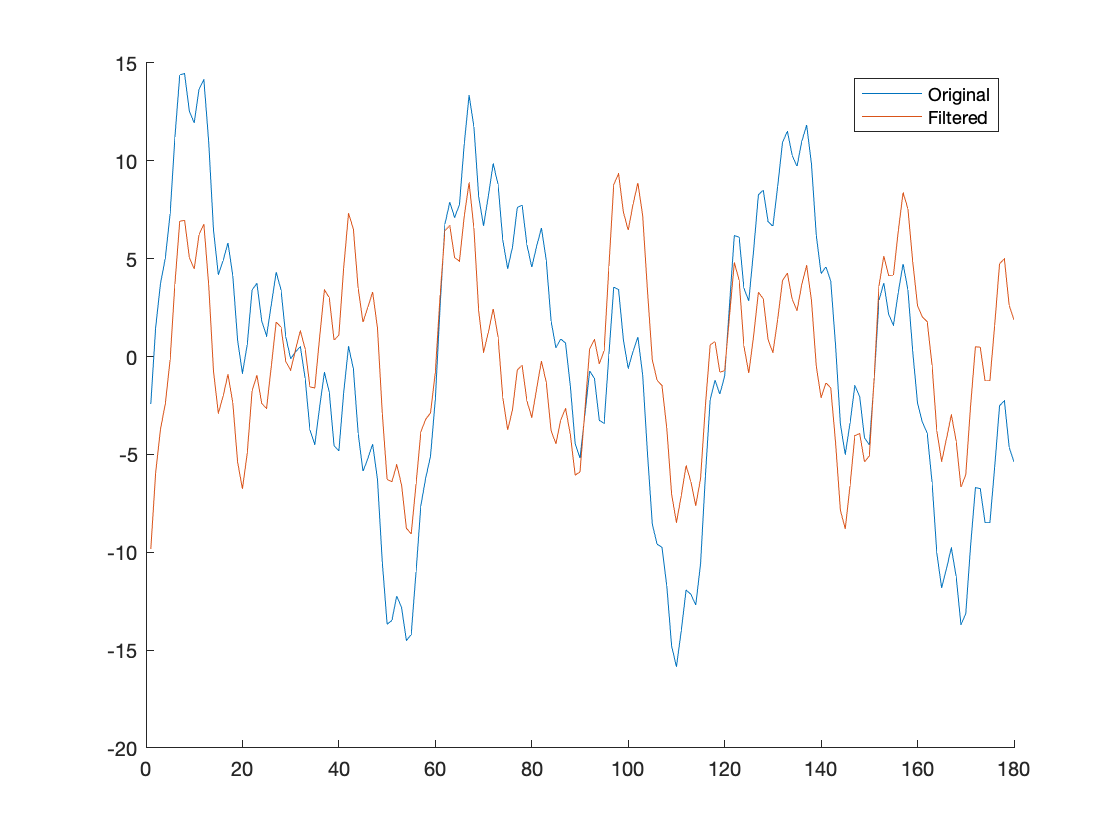

[filtered_y, I, S] = hpfilter(y, TR, 100, length(y));

figure; hold on;
plot(y); 
plot(filtered_y)
legend({'Original' 'Filtered'})

For the next time series (e.g., Y_new), you can just multiply S*y_new to apply the filter.

#### Questions to answer: 

- Try exploring different HP filter cutoffs so you can remove as much of the drift as possible, but leave the task signal intact. Plot the results.

- If you remove the task signal of interest (which has a periodicity around 36 sec), what is left? What would happen to your task regressor in this case?

#### Filtering: Wrap-up and key ideas

Here are a few key points: 

- **Don't filter out the signals of interest in your data** (the ones you are modeling in your design matrix).  

- If you are going to pre-filter, filter *both* the data and the design matrix. 